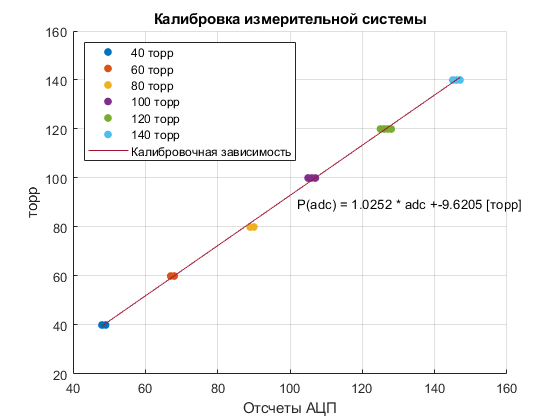

close all;
clear variables;

adc40 = fscanf(fopen('data/calibration_1.txt'), '%d');
adc60 = fscanf(fopen('data/calibration_2.txt'), '%d');
adc80 = fscanf(fopen('data/calibration_3.txt'), '%d');
adc100 = fscanf(fopen('data/calibration_4.txt'), '%d');
adc120 = fscanf(fopen('data/calibration_5.txt'), '%d'); 
adc140 = fscanf(fopen('data/calibration_6.txt'), '%d');

fclose('all');

torr40 = ones(length(adc40), 1) * 40;
torr60 = ones(length(adc60), 1) * 60;
torr80 = ones(length(adc80), 1) * 80;
torr100 = ones(length(adc100), 1) * 100;
torr120 = ones(length(adc120), 1) * 120;
torr140 = ones(length(adc140), 1) * 140;

cAdc = [adc40; adc60; adc80; adc100; adc120; adc140];
cTorr = [torr40; torr60; torr80; torr100; torr120; torr140];

c = polyfit(cAdc, cTorr, 1);

cFigure = figure('Name', 'Калибровка', 'NumberTitle', "off");
hold all;

plot(adc40, torr40, '.', 'MarkerSize', 20);
plot(adc60, torr60, '.', 'MarkerSize', 20);
plot(adc80, torr80, '.', 'MarkerSize', 20);
plot(adc100, torr100, '.', 'MarkerSize', 20);
plot(adc120, torr120, '.', 'MarkerSize', 20);
plot(adc140, torr140, '.', 'MarkerSize', 20);

plot(cAdc, polyval(c, cAdc));

legend('40 торр', '60 торр', '80 торр', '100 торр', '120 торр', '140 торр', 'Калибровочная зависимость', 'Location', 'NorthWest');

grid on;
xlabel('Отсчеты АЦП');
ylabel('торр');
title('Калибровка измерительной системы');
text(mean(cAdc) * 1.05, mean(cTorr), ['P(adc) = ', num2str(c(1)), ' * adc +', num2str(c(2)), ' [торр]']);